# 3.2—3.6 DFT 核心概念：教师课堂演示（四张图）

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。 仅使用基础 MATLAB（不依赖 Signal Processing Toolbox）。 图和本次核验数据写入同目录 results。数值与 dft_lab.py 中的教学补充例一致。 每张图先让学生预测，再运行，再解释。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');   % 由 build_mlx 设置：Live Script 里每格单独一张图，便于阅读；普通运行时拼成一张图存 PNG
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end   % 图例：Live 模式放图下方不压数据；拼图模式自动避让
outdir = fullfile(fileparts(mfilename('fullpath')), 'results');
if ~exist(outdir, 'dir'), mkdir(outdir); end
db = @(v) 20*log10(max(abs(v), 1e-12));

## 演示1：圆周卷积与线性卷积——补零长度不够就会折叠

预测：x=[1,2,3]，h=[2,3,1,2]，线性卷积有几点？5点圆周卷积哪一项会被折回？

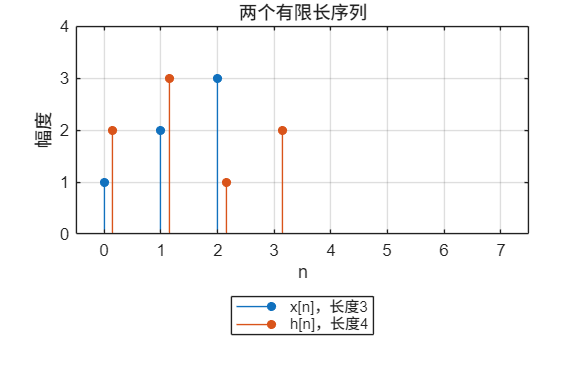

x = [1 2 3]; h = [2 3 1 2];
linearConv = conv(x, h);                 % 长度 3+4-1 = 6
circ5 = circular_convolution(x, h, 5);   % 长度 5：第6项折回到 n=0
circ6 = circular_convolution(x, h, 6);   % 长度 6：等于线性卷积
circ8 = circular_convolution(x, h, 8);   % 长度 8：尾部两点为补零

if ~LIVE, f1 = figure('Name','01 圆周卷积与线性卷积','Color','w','Position',[60 40 1250 820]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); stem(0:2, x, 'filled', 'MarkerSize', 5); hold on;
stem((0:3)+0.15, h, 'filled', 'MarkerSize', 5, 'Color', [0.85 0.33 0.1]); grid on;
xlim([-0.5 7.5]); ylim([0 4]); legend('x[n]，长度3','h[n]，长度4');
title('两个有限长序列'); xlabel('n'); ylabel('幅度');

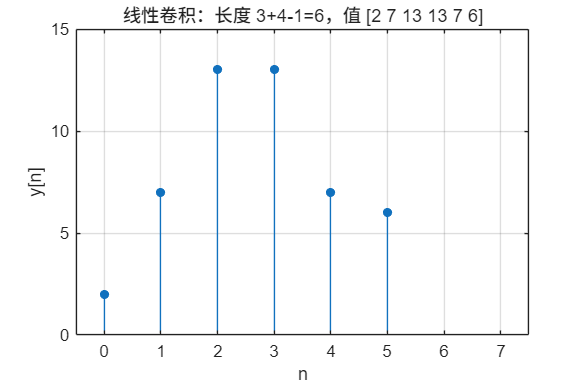

newpanel(); stem(0:5, linearConv, 'filled', 'MarkerSize', 5); grid on;
xlim([-0.5 7.5]); ylim([0 15]);
title('线性卷积：长度 3+4-1=6，值 [2 7 13 13 7 6]'); xlabel('n'); ylabel('y[n]');

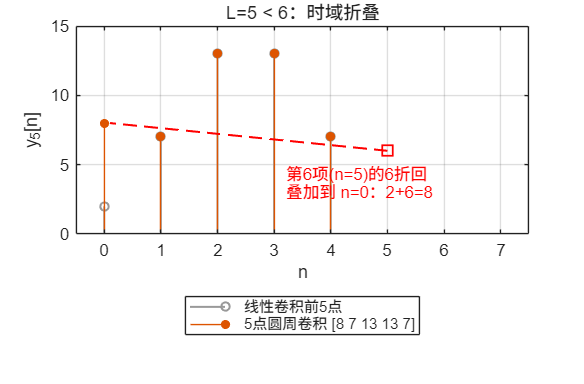

newpanel(); stem(0:4, linearConv(1:5), 'Color', [0.6 0.6 0.6], 'LineWidth', 1.2, 'MarkerSize', 5); hold on;
stem(0:4, circ5, 'filled', 'MarkerSize', 5); grid on; xlim([-0.5 7.5]); ylim([0 15]);
plot([5 0.1], [6 8], 'r--', 'LineWidth', 1.2); plot(5, 6, 'rs', 'MarkerSize', 8, 'LineWidth', 1.5);
text(3.2, 4.3, '第6项(n=5)的6折回', 'Color', 'r'); text(3.2, 3.0, '叠加到 n=0：2+6=8', 'Color', 'r');
legend('线性卷积前5点','5点圆周卷积 [8 7 13 13 7]');
title('L=5 < 6：时域折叠'); xlabel('n'); ylabel('y_5[n]');

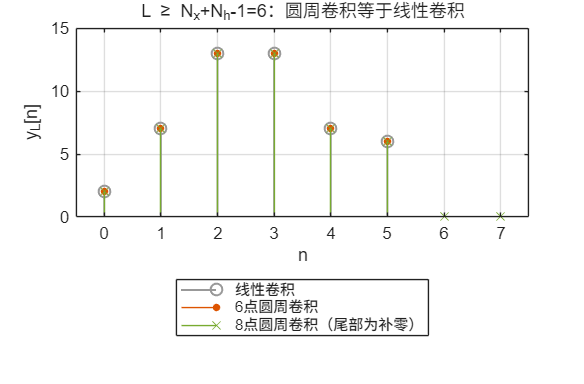

newpanel(); stem(0:5, linearConv, 'Color', [0.6 0.6 0.6], 'LineWidth', 1.2, 'MarkerSize', 7); hold on;
stem(0:5, circ6, 'filled', 'MarkerSize', 4); stem(0:7, circ8, 'x', 'MarkerSize', 7, 'Color', [0.47 0.67 0.19]);
grid on; xlim([-0.5 7.5]); ylim([0 15]);
legend('线性卷积','6点圆周卷积','8点圆周卷积（尾部为补零）');
title('L \geq N_x+N_h-1=6：圆周卷积等于线性卷积'); xlabel('n'); ylabel('y_L[n]');

if ~LIVE, sgtitle('用 fft 做卷积前先补零到 L \geq N_x+N_h-1；否则越界样本绕回叠加'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir,'01-circular-convolution.png'), 'Resolution', 150); end

## 演示2：补零与频域采样——网格变密不等于信息变多

预测：512点记录补零到4096点，谱峰会变尖吗？两个相差8 Hz的单音能分开吗？

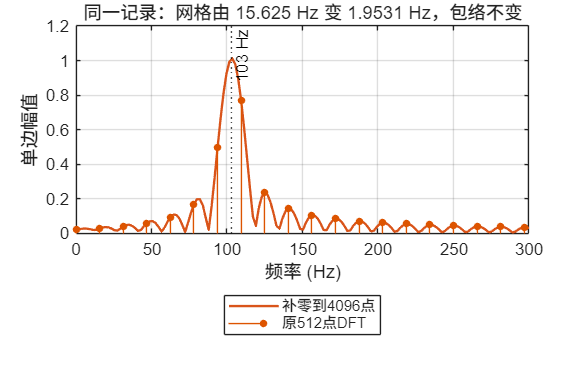

fs = 8000; M = 512; Npad = 4096; f0 = 103;          % 103 Hz 不在 fs/M=15.625 Hz 网格上
n = 0:M-1; xTone = cos(2*pi*f0*n/fs);
X512 = fft(xTone); X4096 = fft(xTone, Npad);
fGrid512 = (0:M-1)*fs/M; fGrid4096 = (0:Npad-1)*fs/Npad;
fA = 1000; fB = 1008;                                 % 相距 8 Hz，约半个 fs/M 网格
pair512 = cos(2*pi*fA*n/fs) + cos(2*pi*fB*n/fs);
M2 = 2048; n2 = 0:M2-1;
pair2048 = cos(2*pi*fA*n2/fs) + cos(2*pi*fB*n2/fs);   % 记录长度增加 4 倍，不补零
xLong = 1:6;                                          % 频域采样：对完整 DTFT 取 4 点
sampledDTFT = exp(-2j*pi*(0:3)'*(0:5)/4) * xLong(:);
folded = real(ifft(sampledDTFT));                     % 期望 [6 8 3 4]

if ~LIVE, f2 = figure('Name','02 补零与频域采样','Color','w','Position',[100 80 1250 820]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); plot(fGrid4096, 2*abs(X4096)/M, 'Color', [0.85 0.33 0.1], 'LineWidth', 1.4); hold on;
stem(fGrid512, 2*abs(X512)/M, 'filled', 'MarkerSize', 4); grid on; xlim([0 300]);
xline(f0, 'k:', '103 Hz'); legend('补零到4096点','原512点DFT');
title(sprintf('同一记录：网格由 %.3f Hz 变 %.4f Hz，包络不变', fs/M, fs/Npad));
xlabel('频率 (Hz)'); ylabel('单边幅值');

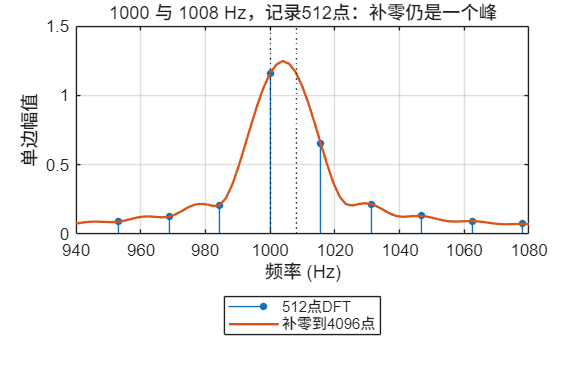

newpanel(); stem(fGrid512, 2*abs(fft(pair512))/M, 'filled', 'MarkerSize', 4); hold on;
plot(fGrid4096, 2*abs(fft(pair512, Npad))/M, 'Color', [0.85 0.33 0.1], 'LineWidth', 1.4); grid on;
xlim([940 1080]); xline(fA, 'k:'); xline(fB, 'k:');
legend('512点DFT','补零到4096点');
title(sprintf('%d 与 %d Hz，记录512点：补零仍是一个峰', fA, fB)); xlabel('频率 (Hz)'); ylabel('单边幅值');

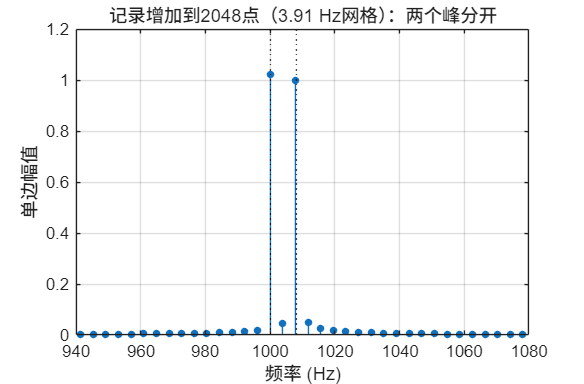

newpanel(); stem((0:M2-1)*fs/M2, 2*abs(fft(pair2048))/M2, 'filled', 'MarkerSize', 4); grid on;
xlim([940 1080]); xline(fA, 'k:'); xline(fB, 'k:');
title(sprintf('记录增加到2048点（%.2f Hz网格）：两个峰分开', fs/M2)); xlabel('频率 (Hz)'); ylabel('单边幅值');

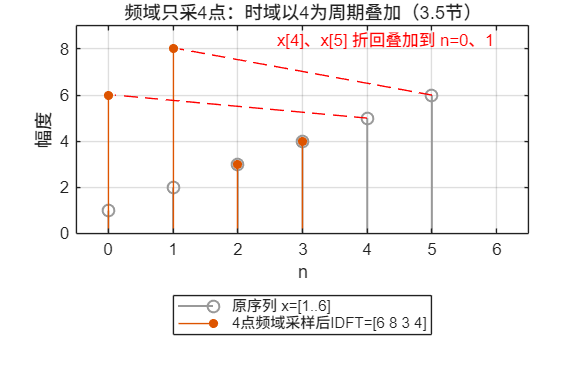

newpanel(); stem(0:5, xLong, 'Color', [0.6 0.6 0.6], 'LineWidth', 1.2, 'MarkerSize', 7); hold on;
stem(0:3, folded, 'filled', 'MarkerSize', 5); grid on; xlim([-0.5 6.5]); ylim([0 9]);
plot([4 0.1], [5 6], 'r--'); plot([5 1.1], [6 8], 'r--');
text(2.6, 8.4, 'x[4]、x[5] 折回叠加到 n=0、1', 'Color', 'r');
legend('原序列 x=[1..6]','4点频域采样后IDFT=[6 8 3 4]');
title('频域只采4点：时域以4为周期叠加（3.5节）'); xlabel('n'); ylabel('幅度');

if ~LIVE, sgtitle('补零只把同一条 DTFT 采得更密；分辨两个频率靠记录长度与窗，不靠 FFT 点数'); end
if ~LIVE, prepare_export(f2); end
if ~LIVE, exportgraphics(f2, fullfile(outdir,'02-zero-padding.png'), 'Resolution', 150); end

## 演示3：泄漏——记录里不是整数个周期，能量就漏到别的频点

预测：512点里恰好7个周期与7.3个周期，谱线有什么区别？先看拼接处是否连续。

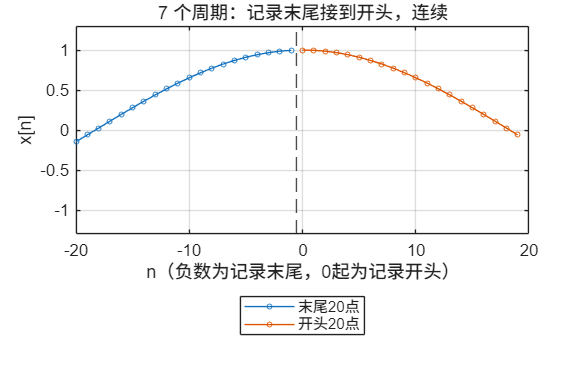

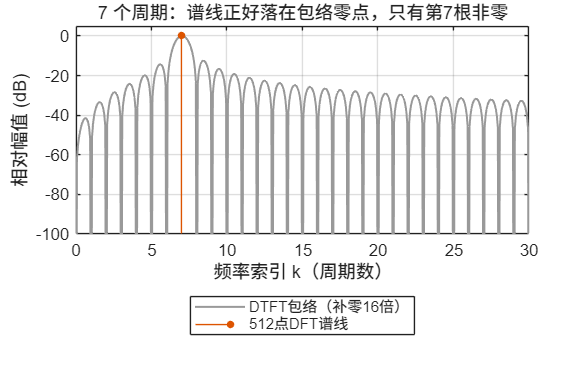

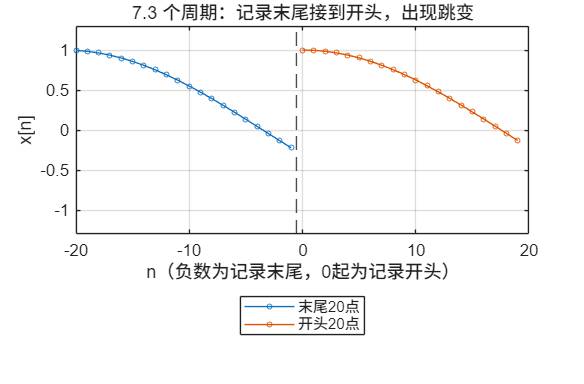

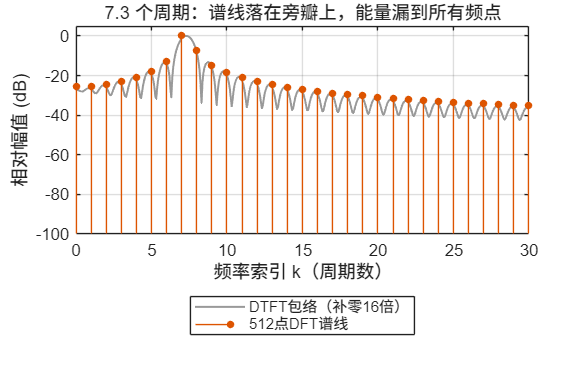

cyc = [7, 7.3];
sig = [cos(2*pi*cyc(1)*n/M); cos(2*pi*cyc(2)*n/M)];
S = fft(sig, [], 2); Spad = fft(sig, 16*M, 2);
binsPad = (0:16*M-1)/16;
timeNote = {'，连续', '，出现跳变'};
specNote = {'谱线正好落在包络零点，只有第7根非零', '谱线落在旁瓣上，能量漏到所有频点'};
if ~LIVE, f3 = figure('Name','03 泄漏','Color','w','Position',[140 100 1250 820]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
for j = 1:2
    tail = sig(j, end-19:end); head = sig(j, 1:20);
    newpanel(j); plot(-20:-1, tail, '-o', 'MarkerSize', 3); hold on;
    plot(0:19, head, '-o', 'MarkerSize', 3); xline(-0.5, 'k--'); grid on; ylim([-1.3 1.3]);
    title(sprintf('%g 个周期：记录末尾接到开头%s', cyc(j), timeNote{j}));
    xlabel('n（负数为记录末尾，0起为记录开头）'); ylabel('x[n]');
    legend('末尾20点','开头20点');
    newpanel(j+2); plot(binsPad, db(Spad(j,:)/max(abs(Spad(j,:)))), 'Color', [0.6 0.6 0.6], 'LineWidth', 1.2); hold on;
    stem(0:M-1, db(S(j,:)/max(abs(S(j,:)))), 'filled', 'MarkerSize', 4, 'BaseValue', -100); grid on;
    xlim([0 30]); ylim([-100 5]);
    legend('DTFT包络（补零16倍）','512点DFT谱线');
    title(sprintf('%g 个周期：%s', cyc(j), specNote{j}));
    xlabel('频率索引 k（周期数）'); ylabel('相对幅值 (dB)');
end

if ~LIVE, sgtitle('矩形窗下泄漏来自记录端点的跳变；DFT 谱线只是 DTFT 包络上的采样'); end
if ~LIVE, prepare_export(f3); end
if ~LIVE, exportgraphics(f3, fullfile(outdir,'03-leakage.png'), 'Resolution', 150); end

## 演示4：窗函数——主瓣宽度与旁瓣衰减不能同时最好

预测：加 Hann 窗后主瓣变宽还是变窄？一个比主音低 46 dB 的弱音，矩形窗能看见吗？

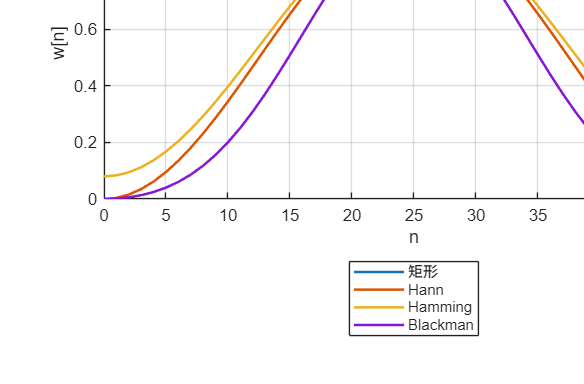

Nw = 51; nw = (0:Nw-1)';
winNames = {'矩形', 'Hann', 'Hamming', 'Blackman'};
winData = {ones(Nw,1), 0.5-0.5*cos(2*pi*nw/(Nw-1)), 0.54-0.46*cos(2*pi*nw/(Nw-1)), ...
    0.42-0.5*cos(2*pi*nw/(Nw-1))+0.08*cos(4*pi*nw/(Nw-1))};
Nfw = 8192; binAxis = (0:Nfw-1)/Nfw*Nw;                  % 单位：周期/窗长（=DFT 频点间隔）
sidelobe = zeros(1,4); mainlobeNull = zeros(1,4);
if ~LIVE, f4 = figure('Name','04 窗函数','Color','w','Position',[180 120 1250 820]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); hold on;
for j = 1:4, plot(nw, winData{j}, 'LineWidth', 1.5); end
grid on; ylim([0 1.1]); legend(winNames); title('51点对称窗的形状'); xlabel('n'); ylabel('w[n]');

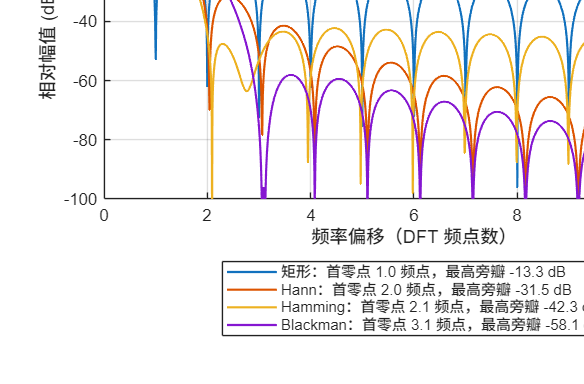

newpanel(); hold on;
for j = 1:4
    W = abs(fft(winData{j}, Nfw)); W = W/W(1);
    plot(binAxis, db(W), 'LineWidth', 1.3);
    half = W(1:Nfw/2); firstNull = find(diff(half) > 0, 1);            % 第一个上升点即主瓣第一零点
    mainlobeNull(j) = binAxis(firstNull);
    sidelobe(j) = db(max(half(firstNull:end)));
end
grid on; xlim([0 12]); ylim([-100 5]);
winLabels = cell(1,4);
for j = 1:4
    winLabels{j} = sprintf('%s：首零点 %.1f 频点，最高旁瓣 %.1f dB', winNames{j}, mainlobeNull(j), sidelobe(j));
end
legend(winLabels);
title('窗的频谱：主瓣越窄，旁瓣越高'); xlabel('频率偏移（DFT 频点数）'); ylabel('相对幅值 (dB)');

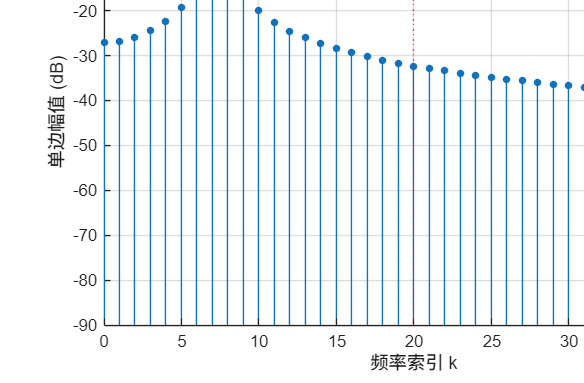

strongCyc = 7.3; weakCyc = 20; weakAmp = 0.005;          % 弱音比主音低 46 dB
two = cos(2*pi*strongCyc*n/M) + weakAmp*cos(2*pi*weakCyc*n/M);
hannP = 0.5-0.5*cos(2*pi*(0:M-1)/M);                     % 周期型 Hann，配合 DFT 使用
specRect = abs(fft(two))/M*2; specHann = abs(fft(two.*hannP))/sum(hannP)*2;
newpanel(); stem(0:M-1, db(specRect), 'filled', 'MarkerSize', 4, 'BaseValue', -90); hold on;
xline(weakCyc, 'r:', '20周期弱音'); grid on; xlim([0 40]); ylim([-90 5]);
title('矩形窗：弱音被 7.3 周期主音的泄漏淹没'); xlabel('频率索引 k'); ylabel('单边幅值 (dB)');

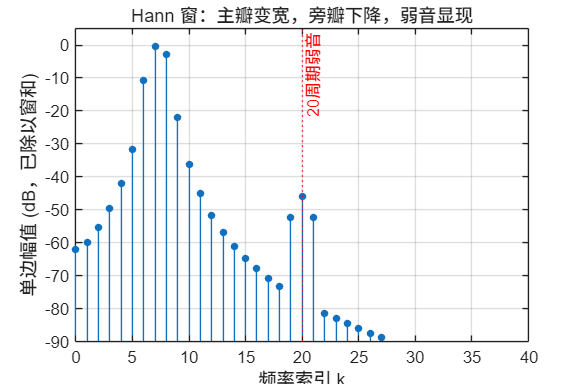

newpanel(); stem(0:M-1, db(specHann), 'filled', 'MarkerSize', 4, 'BaseValue', -90); hold on;
xline(weakCyc, 'r:', '20周期弱音'); grid on; xlim([0 40]); ylim([-90 5]);
title('Hann 窗：主瓣变宽，旁瓣下降，弱音显现'); xlabel('频率索引 k'); ylabel('单边幅值 (dB，已除以窗和)');

if ~LIVE, sgtitle('选窗是取舍：分辨相近频率要窄主瓣，发现弱信号要低旁瓣'); end
if ~LIVE, prepare_export(f4); end
if ~LIVE, exportgraphics(f4, fullfile(outdir,'04-windows.png'), 'Resolution', 150); end

## 教师核验：与 dft_lab.py 的教学补充例逐项对照

checks = struct();
checks.linear_by_hand = max(abs(linearConv - [2 7 13 13 7 6]));
checks.circular_5_folded = max(abs(circ5 - [8 7 13 13 7]));
checks.linear_via_fft_6 = max(abs(circ6 - linearConv));
checks.linear_via_fft_8 = max(abs(circ8 - [linearConv 0 0]));
checks.frequency_sampling_time_folding = max(abs(folded(:)' - [6 8 3 4]));
checks.zero_padding_same_dtft_grid = max(abs(X4096(1:8:end) - X512));
nA = 0:511;
checks.alias_400_to_200_at_fs600 = max(abs(cos(2*pi*400*nA/600) - cos(2*pi*200*nA/600)));
coherent = S(1,:); coherent([8, M-6]) = 0;               % k=7 与 k=505（MATLAB 索引 8、506）
checks.coherent_rectangular_other_bins = max(abs(coherent))/max(abs(S(1,:)));
offgrid = S(2,:); offgrid([8, M-6]) = 0;
offgridLeakNorm = norm(offgrid);
amp = 2.4; kTone = 19; sigAmp = amp*cos(2*pi*kTone*n/M);
padAmp = abs(fft(sigAmp.*hannP, Npad))/sum(hannP)*2;
checks.hann_coherent_gain_padding_amplitude = abs(padAmp(kTone*8+1) - amp);
rectContrast = db(specRect(weakCyc+1)) - db(specRect(weakCyc-2));
hannContrast = db(specHann(weakCyc+1)) - db(specHann(weakCyc-2));
% 弱音频点上叠加了主音经 Hann 窗后的残余泄漏（约 -76 dB），只能近似恢复 0.005。
weakToneRelError = abs(specHann(weakCyc+1) - weakAmp)/weakAmp;
tol = 1e-10;
names = fieldnames(checks);
for j = 1:numel(names)
    assert(checks.(names{j}) < tol, '核验未通过：%s = %g', names{j}, checks.(names{j}));
end
assert(offgridLeakNorm > 1, '7.3周期应出现泄漏');
assert(sidelobe(1) > -14 && sidelobe(1) < -12.5, '矩形窗最高旁瓣异常');
assert(sidelobe(2) > -33 && sidelobe(2) < -30, 'Hann窗最高旁瓣异常');
assert(all(diff(sidelobe) < 0), '旁瓣应按矩形、Hann、Hamming、Blackman递减');
assert(all(diff(mainlobeNull) >= 0), '主瓣应按同一顺序变宽或不变');
assert(hannContrast > 10 && rectContrast < 5, '弱音对比度不符合预期');
assert(weakToneRelError < 0.05, 'Hann 窗下弱音幅值偏差超过5%%');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'fs', fs, 'record_samples', M, 'padded_samples', Npad, 'original_grid_hz', fs/M, 'padded_grid_hz', fs/Npad, ...
    'tone_pair_hz', [fA fB], 'leakage_cycles', cyc, 'window_length', Nw, ...
    'window_names', {winNames}, 'window_first_null_bins', mainlobeNull, 'window_peak_sidelobe_db', sidelobe, ...
    'weak_tone_contrast_db_rect', rectContrast, 'weak_tone_contrast_db_hann', hannContrast, ...
    'weak_tone_amplitude_hann', specHann(weakCyc+1), 'weak_tone_rel_error_hann', weakToneRelError, ...
    'offgrid_leakage_norm', offgridLeakNorm, 'checks_max_abs_error', checks, 'all_checks_passed', true);
fid = fopen(fullfile(outdir,'verification.json'), 'w', 'n', 'UTF-8');
assert(fid >= 0, '无法创建核验记录');
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics);

                matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                        run_at: '2026-09-18 18:40:37'
                            fs: 8000
                record_samples: 512
                padded_samples: 4096
              original_grid_hz: 15.6250
                padded_grid_hz: 1.9531
                  tone_pair_hz: [1000 1008]
                leakage_cycles: [7 7.3000]
                 window_length: 51
                  window_names: {'矩形'  'Hann'  'Hamming'  'Blackman'}
        window_first_null_bins: [1.0023 2.0420 2.0918 3.0630]
       window_peak_sidelobe_db: [-13.2503 -31.4675 -42.3132 -58.1124]
    weak_tone_contrast_db_rect: -2.1633
    weak_tone_contrast_db_hann: 24.8118
      weak_tone_amplitude_hann: 0.0051
      weak_tone_rel_error_hann: 0.0136
          offgrid_leakage_norm: 186.4075
          checks_max_abs_error: [1×1 struct]
             all_checks_passed: 1



fprintf('\n课堂图已保存到：%s\n', outdir);


课堂图已保存到：C:\Users\Administrator\AppData\Local\Temp\Editor_lhbfa\results



function y = circular_convolution(x, h, L)
% L 点圆周卷积；要求 L 不小于两输入长度，避免 fft(x,L) 的隐式截断。
assert(L >= max(numel(x), numel(h)), '本函数要求 L 不小于两输入长度');
y = real(ifft(fft(x, L) .* fft(h, L)));
end

function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList)
    axesList(a).Toolbar.Visible = 'off';
end
drawnow;
end